%% =======================================================
% Subject-level scalp topography with assumption checking
% Normality -> variance test -> t-test or ranksum
%% =======================================================
clear; clc; close all;

dataFolder = 'C:\assabNEW\subs\';
locPath = 'C:\kar\matlab\zemestun\loc57.mat';
load(locPath, 'loc57');

MAX_TRIALS = 10;
fs = 200;
bandFreqs = [1 3; 4 7; 8 12; 13 25; 30 40];
bandNames = {'Delta','Theta','Alpha','Beta','Gamma'};
nBands = size(bandFreqs,1);

%% Group lists
Male = { ...
    'CBM00214','CBM00163','CBM00074','CBM00048','CBM00122','CBM00259', ...
    'CBM00152','CBM00182','CBM00046','CBM00101','CBM00281','CBM00150', ...
    'CBM00002','CBM00262','CBM00092','CBM00043','CBM00041','CBM00109', ...
    'CBM00212','CBM00144','CBM00215','CBM00264','CBM00274','CBM00235', ...
    'CBM00071','CBM00261','CBM00053','CBM00051','CBM00068','CBM00129', ...
    'CBM00155','CBM00236','CBM00062','CBM00248','CBM00119', ...
    'CBM00034','CBM00266','CBM00205','CBM00167','CBM00279','CBM00223', ...
    'CBM00031','CBM00127','CBM00094','CBM00117','CBM00088','CBM00110', ...
    'CBM00079','CBM00044','CBM00025','CBM00010','CBM00284','CBM00135', ...
    'CBM00008','CBM00073','CBM00075','CBM00085','CBM00192','CBM00111', ...
    'CBM00103' };

Female = { ...
    'CBM00011','CBM00207','CBM00009','CBM00081','CBM00269','CBM00156', ...
    'CBM00195','CBM00196','CBM00166','CBM00206','CBM00202','CBM00157', ...
    'CBM00158','CBM00169','CBM00171','CBM00159','CBM00221','CBM00210', ...
    'CBM00023','CBM00076' };

allSubjects = [Female(:); Male(:)];

fprintf('Female subjects: %d\n', numel(Female));

Female subjects: 20


fprintf('Male subjects: %d\n', numel(Male));

Male subjects: 60


%% Find subject files (Male + Female only)

files = dir(fullfile(dataFolder, '*_middle_matrix_*.mat'));

validFiles = [];

for f = 1:numel(files)

    [~, name] = fileparts(files(f).name);

    tok = regexp(name, '_middle_matrix_(\d+)', 'tokens');

    if isempty(tok)
        continue;
    end

    subjNum = str2double(tok{1}{1});
    subjCode = sprintf('CBM%05d', subjNum);

    % Keep only subjects listed in Male or Female
    if ismember(subjCode, [Male(:); Female(:)])
        validFiles = [validFiles; files(f)];
    end

end

fprintf('Found valid subject files: %d\n', numel(validFiles));

Found valid subject files: 80



%% Filters
warning('off','MATLAB:singularMatrix');
filters = cell(nBands,1);
for b = 1:nBands
    Wn = bandFreqs(b,:) / (fs/2);
    [bb, aa] = butter(3, Wn, 'bandpass');
    filters{b}.b = double(bb);
    filters{b}.a = double(aa);
end

%% Storage
allFemaleSubjPower = cell(nBands,57);
allMaleSubjPower   = cell(nBands,57);

allTopoFemale = nan(nBands,57);
allTopoMale   = nan(nBands,57);

%% Helper: normality check using kstest on z-scored data
checkNormal = @(x) localNormalityCheck(x);

fprintf('\nStart processing subjects...\n');


Start processing subjects...



for b = 1:nBands
    fprintf('\nBand %d/%d: %s\n', b, nBands, bandNames{b});

    femaleVals = [];
    maleVals = [];

    for f = 1:numel(files)
        [~, name] = fileparts(files(f).name);
        tok = regexp(name, '_middle_matrix_(\d+)', 'tokens');
        if isempty(tok)
            continue;
        end

        subjNum = str2double(tok{1}{1});
        subjCode = sprintf('CBM%05d', subjNum);

        if ~ismember(subjCode, allSubjects)
            continue;
        end

        filePath = fullfile(dataFolder, files(f).name);

        try
            S = load(filePath);
            if ~isfield(S, 'middleMatrix')
                fprintf('Skipping %s: middleMatrix not found.\n', subjCode);
                continue;
            end

            eeg_full = double(S.middleMatrix);

            if ndims(eeg_full) ~= 3
                fprintf('Skipping %s: data is not 3D.\n', subjCode);
                continue;
            end

            if size(eeg_full,1) > MAX_TRIALS
                eeg = eeg_full(1:MAX_TRIALS,:,:);
            else
                eeg = eeg_full;
            end

            nTrials = size(eeg,1);
            nChan   = size(eeg,2);

            if nChan ~= 57
                fprintf('Skipping %s: channels=%d (expected 57)\n', subjCode, nChan);
                continue;
            end

            bandPow = zeros(nTrials, nChan);

            for tr = 1:nTrials
                for ch = 1:nChan
                    x = squeeze(eeg(tr,ch,:));
                    x = x(:);

                    if numel(x) < 5
                        bandPow(tr,ch) = NaN;
                        continue;
                    end

                    try
                        x_filt = filtfilt(filters{b}.b, filters{b}.a, x);
                    catch
                        x_filt = x;
                    end

                    bandPow(tr,ch) = mean(x_filt.^2, 'omitnan');
                end
            end

            subjTopo = mean(bandPow, 1, 'omitnan');
            subjTopo(~isfinite(subjTopo)) = NaN;

            if ismember(subjCode, Female)
                femaleVals = [femaleVals; subjTopo];
                for ch = 1:57
                    allFemaleSubjPower{b,ch} = [allFemaleSubjPower{b,ch}, subjTopo(ch)];
                end
            elseif ismember(subjCode, Male)
                maleVals = [maleVals; subjTopo];
                for ch = 1:57
                    allMaleSubjPower{b,ch} = [allMaleSubjPower{b,ch}, subjTopo(ch)];
                end
            end

        catch ME
            fprintf('Error processing %s: %s\n', files(f).name, ME.message);
        end
    end

    if ~isempty(femaleVals)
        allTopoFemale(b,:) = mean(femaleVals, 1, 'omitnan');
    end
    if ~isempty(maleVals)
        allTopoMale(b,:) = mean(maleVals, 1, 'omitnan');
    end
end


Band 1/5: Delta

Band 2/5: Theta

Band 3/5: Alpha

Band 4/5: Beta

Band 5/5: Gamma



%% Statistics
pValues = nan(nBands,57);
negLogP = nan(nBands,57);
testUsed = strings(nBands,57);

fprintf('\nRunning channel-wise statistical tests...\n');


Running channel-wise statistical tests...



for b = 1:nBands
    for ch = 1:57
        femaleData = allFemaleSubjPower{b,ch};
        maleData   = allMaleSubjPower{b,ch};

        femaleData = femaleData(isfinite(femaleData));
        maleData   = maleData(isfinite(maleData));

        if numel(femaleData) < 3 || numel(maleData) < 3
            pValues(b,ch) = NaN;
            negLogP(b,ch) = NaN;
            testUsed(b,ch) = "insufficient_data";
            continue;
        end

        [isNormF, pNormF] = localNormalityCheck(femaleData);
        [isNormM, pNormM] = localNormalityCheck(maleData);

        if isNormF && isNormM
            [isEqVar, pVar] = vartest2(femaleData, maleData);

            if isEqVar
                [~, p] = ttest2(femaleData, maleData, 'Vartype', 'equal');
                testUsed(b,ch) = "ttest2_equal";
            else
                [~, p] = ttest2(femaleData, maleData, 'Vartype', 'unequal');
                testUsed(b,ch) = "ttest2_unequal";
            end
        else
            p = ranksum(femaleData, maleData);
            testUsed(b,ch) = "ranksum";
        end

        pValues(b,ch) = p;
        negLogP(b,ch) = -log10(max(p, realmin));
    end

    fprintf('Band %s: mean -log10(p) = %.3f\n', bandNames{b}, mean(negLogP(b,:), 'omitnan'));
end

Band Delta: mean -log10(p) = 0.364
Band Theta: mean -log10(p) = 0.224
Band Alpha: mean -log10(p) = 0.396
Band Beta: mean -log10(p) = 0.648
Band Gamma: mean -log10(p) = 0.382



%% Save
save('topography_subjectlevel_autoStats.mat', ...
    'allTopoFemale','allTopoMale','loc57','bandNames', ...
    'pValues','negLogP','testUsed', ...
    'allFemaleSubjPower','allMaleSubjPower');

fprintf('\nSaved: topography_subjectlevel_autoStats.mat\n');


Saved: topography_subjectlevel_autoStats.mat


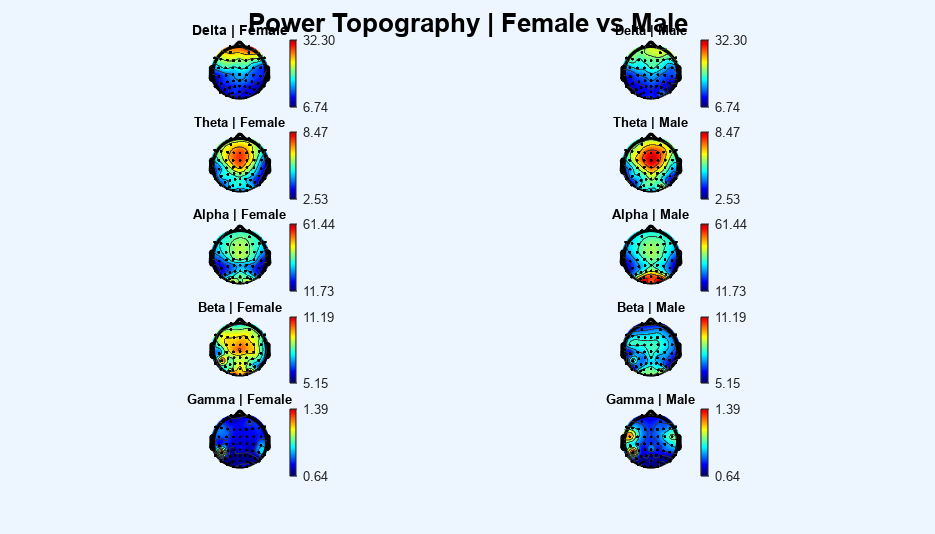

%% Plot 1: Topography Female vs Male
figure('Position', [50 50 1400 800], 'Color', 'w');

for b = 1:nBands
    femaleValsB = allTopoFemale(b,:);
    maleValsB   = allTopoMale(b,:);

    vals = [femaleValsB maleValsB];
    vals = vals(isfinite(vals));

    if isempty(vals)
        mapLims = [0 1];
    else
        mapLims = [min(vals) max(vals)];
        if mapLims(1) == mapLims(2)
            mapLims = [mapLims(1)-1, mapLims(2)+1];
        end
    end

    subplot(nBands, 2, (b-1)*2+1);
    topoplot(femaleValsB, loc57, ...
        'electrodes', 'on', ...
        'style', 'both', ...
        'maplimits', mapLims, ...
        'conv', 'on');

    cb = colorbar;
    cb.Limits = mapLims;
    cb.Ticks = [mapLims(1) mapLims(2)];
    cb.TickLabels = {sprintf('%.2f', mapLims(1)), sprintf('%.2f', mapLims(2))};
    cb.FontSize = 8;
    cb.TickDirection = 'out';

    title(sprintf('%s | Female', bandNames{b}));

    subplot(nBands, 2, (b-1)*2+2);
    topoplot(maleValsB, loc57, ...
        'electrodes', 'on', ...
        'style', 'both', ...
        'maplimits', mapLims, ...
        'conv', 'on');

    cb = colorbar;
    cb.Limits = mapLims;
    cb.Ticks = [mapLims(1) mapLims(2)];
    cb.TickLabels = {sprintf('%.2f', mapLims(1)), sprintf('%.2f', mapLims(2))};
    cb.FontSize = 8;
    cb.TickDirection = 'out';

    title(sprintf('%s | Male', bandNames{b}));
end

sgtitle('Power Topography | Female vs Male', ...
    'FontSize', 16, 'FontWeight', 'bold');

print(gcf, 'power_topography_Fe_M_autoStats.png', '-dpng', '-r300');

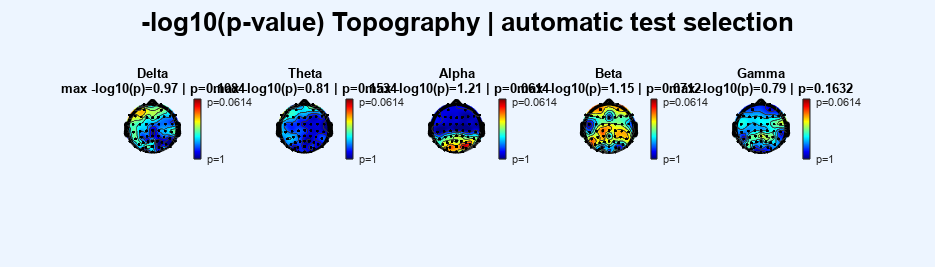

%% Plot 2: -log10(p-value) with correct p-value labels
figure('Position', [50 50 1400 400], 'Color', 'w');

pMax = max(negLogP(:), [], 'omitnan');
if isempty(pMax) || ~isfinite(pMax) || pMax <= 0
    pMax = 1;
end

for b = 1:nBands
    subplot(1, nBands, b);

    bandData = negLogP(b,:);
    topoplot(bandData, loc57, ...
        'electrodes', 'on', ...
        'maplimits', [0 pMax], ...
        'conv', 'on', ...
        'style', 'both');

    maxNegLogP = max(bandData, [], 'omitnan');
    minP = 10^(-maxNegLogP);

    title(sprintf('%s\nmax -log10(p)=%.2f | p=%.4f', ...
        bandNames{b}, maxNegLogP, minP));

    c = colorbar;
    c.Ticks = [0 pMax];
    c.TickLabels = {sprintf('p=1'), sprintf('p=%.4f', 10^(-pMax))};
end

sgtitle('-log10(p-value) Topography | automatic test selection', ...
    'FontSize', 16, 'FontWeight', 'bold');

print(gcf, 'negLogP_topography_autoStats.png', '-dpng', '-r300');


fprintf('\nDone!\n');


Done!



%% ===== Local function =====

function [isNormal, p] = localNormalityCheck(x)
    x = x(:);
    x = x(isfinite(x));

    if numel(x) < 3
        isNormal = false;
        p = NaN;
        return;
    end

    if std(x) == 0
        isNormal = false;
        p = 0;
        return;
    end

    z = (x - mean(x)) / std(x);
    try
        [~, p] = kstest(z);
    catch
        p = NaN;
    end

    isNormal = ~isnan(p) && p > 0.05;
end